clc
clear 
close all

out = load("sim_ntl.mat").out;
out1 = load("sim_tl.mat").out;
load("sim_mod_prev.mat")

#### Comparação das variáveis entre as simulações

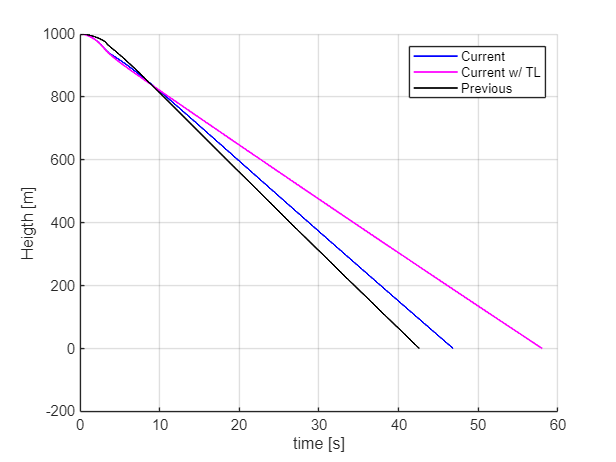

figure()
hold on
plot(out.main_clock, out.vehicle_position(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'Current') % linha preta
plot(out1.main_clock, out1.vehicle_position(:, 3), 'm', 'LineWidth', 1.2, 'DisplayName', 'Current w/ TL') % linha preta

plot(t_final, h_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous') % linha vermelha
grid on
xlabel('time [s]')
ylabel('Heigth [m]')
hold off;
legend("Location","best")

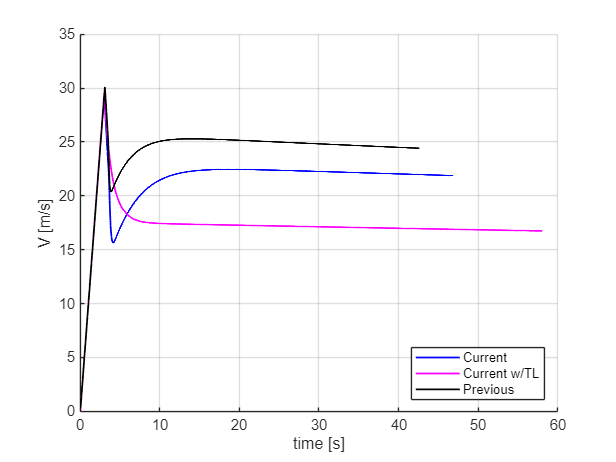

figure()
hold on
plot(out.main_clock, -out.vehicle_velocity(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'Current') % linha preta
plot(out1.main_clock, -out1.vehicle_velocity(:, 3), 'm', 'LineWidth', 1.2, 'DisplayName', 'Current w/TL') % linha preta
plot(t_final, v_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous') % linha vermelha
grid on
xlabel('time [s]')
ylabel('V [m/s]')
hold off;
legend("Location","best")

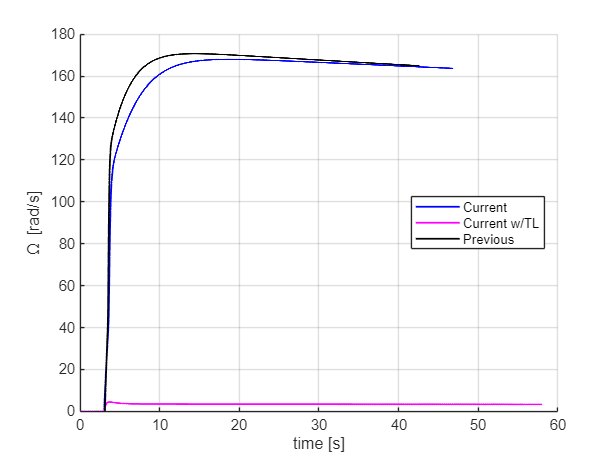

figure()
hold on
plot(out.main_clock, out.rotor_velocity, 'b', 'LineWidth', 1.2, 'DisplayName', 'Current') % linha preta
plot(out1.main_clock, out1.rotor_velocity, 'm', 'LineWidth', 1.2, 'DisplayName', 'Current w/TL') % linha preta
plot(t_final, w_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous') % linha vermelha
grid on
xlabel('time [s]')
ylabel('\Omega [rad/s]')
hold off;
legend("Location","best")

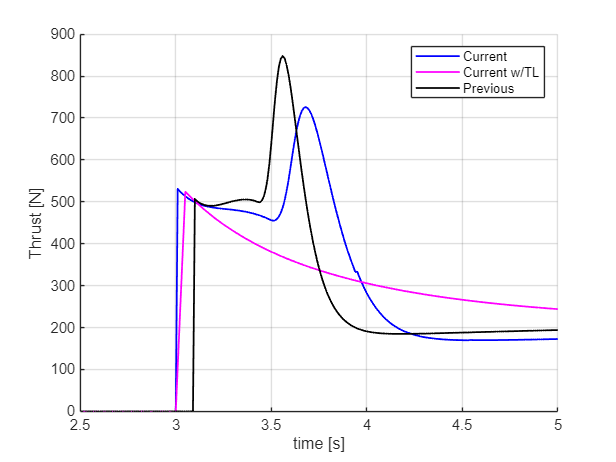

figure()
hold on
plot(out.main_clock, out.F_rotor(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'Current') % linha preta
plot(out1.main_clock, out1.F_rotor(:, 3), 'm', 'LineWidth', 1.2, 'DisplayName', 'Current w/TL') % linha preta
plot(t_final, thrust_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous') % linha vermelha
grid on
xlabel('time [s]')
xlim([2.5 5])
ylabel('Thrust [N]')
hold off;
legend("Location","best")

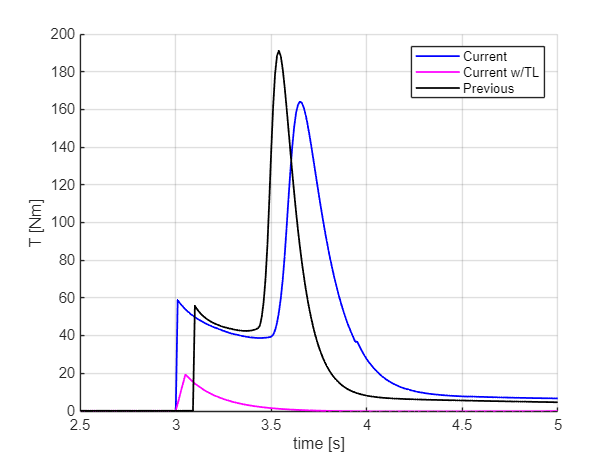

figure()
hold on
plot(out.main_clock, out.T_rotor, 'b', 'LineWidth', 1.2, 'DisplayName', 'Current') % linha preta
plot(out1.main_clock, out1.T_rotor, 'm', 'LineWidth', 1.2, 'DisplayName', 'Current w/TL') % linha preta
plot(t_final,torque_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous') % linha vermelha
grid on
xlabel('time [s]')
ylabel('T [Nm]')
xlim([2.5 5])
hold off;
legend("Location","best")

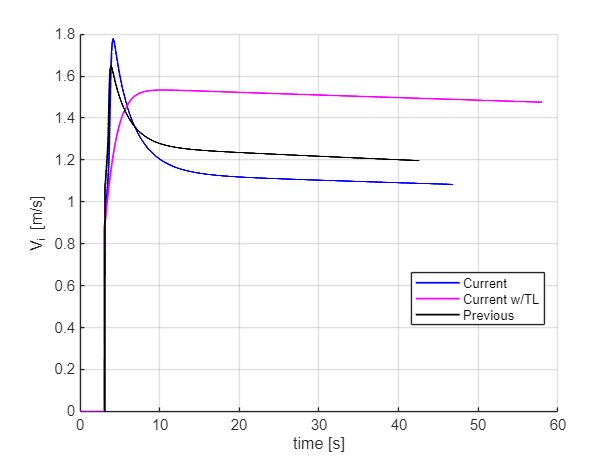

figure()
hold on
plot(out.main_clock, out.rotor_induced_velocity, 'b', 'LineWidth', 1.2, 'DisplayName', 'Current') % linha preta
plot(out1.main_clock, out1.rotor_induced_velocity, 'm', 'LineWidth', 1.2, 'DisplayName', 'Current w/TL') % linha preta
plot(t, vi_vec, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous') % linha vermelha
grid on
xlabel('time [s]')
ylabel('V_i [m/s]')
hold off;
legend("Location","best")